# **Modelo 1Khz Conmutable**

clc 
clear
close all
warning off
% Parámetros del conversor Buck
P_nom_buck = 120;         % Potencia nominal en vatios (W)
Vg = 24;           % Tensión de entrada en voltios (V)
Vout_buck = 12;          % Tensión de salida en voltios (V)
f_sw = 6e3 

f_sw = 6000

fsim=300e6

fsim = 300000000

% Frecuencia de conmutación en hercios (Hz)
% fsim= 100*f_sw
% fsim= 500*f_sw;
Tsim=1/fsim

Tsim = 3.3333e-09

Tsw=1/f_sw

Tsw = 1.6667e-04

Tsimulink=12e-3;

R = Vout_buck^2/P_nom_buck; % Nomila load. CCM
%%%%%%%%%%%%%%%%%%%%%%%
% Ripples Based on nominal parameters
% Delta_IL_buck = 0.4;
Delta_Vout_buck = 0.05*Vout_buck

Delta_Vout_buck = 0.6000


% Cálculo de la corriente de salida del Buck
Iout_buck = P_nom_buck / Vout_buck;
Delta_IL_buck = Iout_buck*0.3

Delta_IL_buck = 3


% Select the simulation option
% Choose CCM
% Choose BCM
% Choose DCM
SimulationType = 'CCM'

SimulationType = 'CCM'


switch SimulationType
    case 'CCM'
        R = Vout_buck^2/P_nom_buck; % Nomila load. CCM
%         R = 3;
        % SimTime = 150e-3;
        RelativeTolerance = 1e-5;
    case 'BCM'
        Icritic = Delta_IL_buck/2
%       R = 50; % Increased to BCM
        R = Vout_buck/Icritic % Increased to BCM

        % SimTime = 150e-3;
        RelativeTolerance = 1e-6;
    case 'DCM'
        R = 100; % Increased to BCM
        % SimTime = 150e-3;
        RelativeTolerance = 1e-10;
end


% Cálculo del ciclo de trabajo (Duty Cycle) del Buck
D_Buck = Vout_buck / Vg;

% Cálculo de la inductancia del Buck
L_buck = (Vg - Vout_buck) / (f_sw * Delta_IL_buck) * D_Buck

L_buck = 3.3333e-04


% Cálculo de la capacitancia del Buck
C_buck = ((1 / f_sw) * (Delta_IL_buck / 2)) / (8 * (Delta_Vout_buck / 2))

C_buck = 1.0417e-04


F_cutLPF = 1/(2*pi*sqrt(L_buck*C_buck));

Scaling_Voltage = (1/Vout_buck)*(2^12)/(3);

% Scaling current to get 1 v at the output.
% Scope Probe scaling must be 5X
Scaling_Current = (1/Iout_buck)*(2^12)/(3);

% conf_step = RespConfig('InputOffset',0,'StepAmplitude',0.4167);
% step(g,conf_step)
% grid on
% 
% G=feedback(g,1)
% stepinfo(G)
% bode(G)

%%%%%%%%%%%%%%


TBPRD =round(200e6/(2*f_sw));

SimTime = 250e-3;        % Simulation Time
% RelativeTolerance: Es la tolerancia relativa de la simulacion en 
% continuo


% Select the simulation option
% Choose CCM
% Choose BCM
% Choose DCM
SimulationType = 'CCM'

SimulationType = 'CCM'


switch SimulationType
    case 'CCM'
        R = Vout_buck^2/P_nom_buck; % Nomila load. CCM
%         R = 3;
        % SimTime = 150e-3;
        RelativeTolerance = 1e-5;
    case 'BCM'
        Icritic = Delta_IL_buck/2
%       R = 50; % Increased to BCM
        R = Vout_buck/Icritic % Increased to BCM

        % SimTime = 150e-3;
        RelativeTolerance = 1e-6;
    case 'DCM'
        R = 100; % Increased to BCM
        % SimTime = 150e-3;
        RelativeTolerance = 1e-10;
end


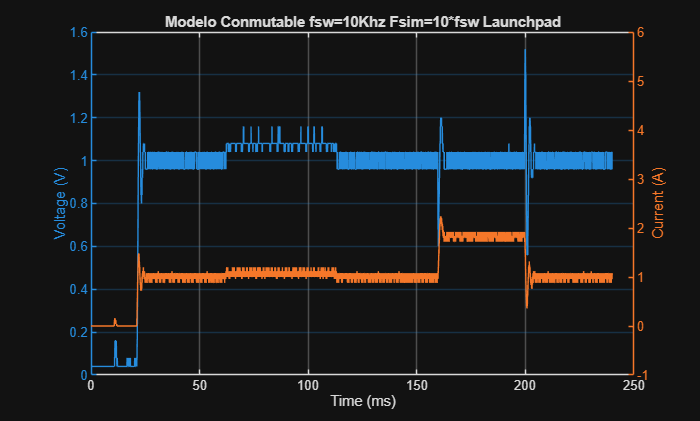

load("data2.mat")
% --- Datos del osciloscopio ---
ch1 = NewFile2(:,2);  % Canal de voltaje
ch2 = NewFile2(:,3);  % Canal de corriente

n = 30000; % número de puntos
muestras = 1.25e6; % tasa de muestreo en Hz (2.50 MSa/s)
T = 1 / muestras; % intervalo entre cada muestra
t_osc = (0:n-1) * T; % vector de tiempo desde 0 hasta el último punto

% Filtrado de los datos del osciloscopio (suavizado)
windowSize = 10; 
ch1_filtrado = movmean(ch1, windowSize); % Filtrado del canal de voltaje
ch2_filtrado = movmean(ch2, windowSize); % Filtrado del canal de corriente

% % --- Datos de Simulink ---
% t_sim = Continuo{1}.Values.Time; % Tiempo del modelo de Simulink
% voltaje_sim = Continuo{1}.Values.Data(:,1); % Voltaje del modelo
% corriente_sim = Continuo{1}.Values.Data(:,2); % Corriente del modelo

%Graficar Datos Obtenidos mediante el osciloscopio
figure
yyaxis left
plot(t_osc*10e3,ch1)
ylabel('Voltage (V)')
yyaxis right
plot(t_osc*10e3,ch2)
ylim([-1 6])
ylabel('Current (A)')
xlabel('Time (ms)')
set(gca,'FontSize',8)
grid on
title('Modelo Conmutable fsw=10Khz Fsim=10*fsw Launchpad')


block_path1 = 'DiscreteBuck_Offline_Control/Buck Converter Swich Model/Discrete-Time Integrator';
block_path2 = 'DiscreteBuck_Offline_Control/Buck Converter Swich Model/Discrete-Time Integrator1';
block_path_Control = 'DiscreteBuck_Offline_Control/Integral1';

% Types of integrators
% Type_Integrator = 'Forward Euler';
% Type_Integrator = 'Backward Euler';
Type_Integrator = 'Trapezoidal';

load_system("DiscreteBuck_Offline_Control.slx");
set_param(block_path1, 'IntegratorMethod', Type_Integrator);
set_param(block_path2, 'IntegratorMethod', Type_Integrator);

% set_param('DiscreteBuck_Offline_Control/Integral1', 'P', num2str(C_pi.Kp));
% set_param('DiscreteBuck_Offline_Control/Integral1', 'I', num2str(C_pi.Ki));


sim("DiscreteBuck_Offline_Control.slx")

Simulation aborted

figure
tiledlayout(3,1)

ax1 = nexttile;
plot(ax1,ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,1))
ylabel(ax1,'V_o_u_t (V)')
grid on
grid minor

ax2 = nexttile;
plot(ax2,ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,2))
ylabel(ax2,'I_i_n_d (A)')
grid on
grid minor

ax3 = nexttile;
plot(ax3,ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,3))
ylabel(ax3,'Duty')
xlabel(ax3,'Time (s)')
grid on
grid minor


%%% Comparisson between Discrete and Continuous Simulation
close all
figure
plot((t_osc*10)-0.00302,ch1_filtrado,...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,1))
grid on
grid minor
ylabel('V_o_u_t (V)')
xlabel('Time (s)')
ylim([0 2])
xlim([-0.008 22*10e-3])

figure
plot((t_osc*10)-0.00302,ch2_filtrado,...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,2))
grid on
grid minor
ylabel('I_i_n_d (A)')
xlabel('Time (s)')
ylim([0 3])
xlim([-0.008  22*10e-3])


% %Graficar Datos del modelo continuo en simulink
% figure
% yyaxis left
% plot(Continuo{1}.Values. Time*10e3,Continuo{1}.Values.Data(:,1))
% ylabel('Voltage (V)')
% yyaxis right
% plot(Continuo{1}.Values. Time*10e3,Continuo{1}.Values.Data(:,2))
% ylim([0 1.5])
% ylabel('Current (A)')
% xlabel('Time (ms)')
% set(gca,'FontSize',8)
% grid on
% title('Modelo Conmutable fsw=5Khz Fsim=5*fsw Simulink')
% 
% 
% --- Ajuste de tiempo de Simulink (Desplazar el tiempo en 0.04 segundos) ---
% tiempo_desfase = 0.00406; % 40 ms (tiempo inicial de los datos del osciloscopio)
% t_sim_desplazado = t_sim + tiempo_desfase; % 
% 
% tiempo_desfase1 = 0.0041; % 40 ms (tiempo inicial de los datos del osciloscopio)
% t_sim_desplazado1 = t_sim + tiempo_desfase1; % Desplazar el tiempo de Simulink para que inicie en 0.04s
% 
% % --- Graficar datos ajustados ---
% figure;
% 
% % Comparación de voltaje (yyaxis left)
% subplot(1,1,1);
% yyaxis left;
% plot(t_osc*10e3, ch1_filtrado, 'b-', 'DisplayName', 'Osciloscopio (Voltaje)'); % Datos del osciloscopio
% hold on;
% plot(t_sim_desplazado1*10e3, voltaje_sim, 'r--', 'DisplayName', 'Simulink (Voltaje)'); % Datos de Simulink con desplazamiento
% ylabel('Voltage (V)');
% legend;
% grid on;
% 
% % Comparación de corriente (yyaxis right)
% yyaxis right;
% plot(t_osc*10e3, ch2_filtrado, 'b-', 'DisplayName', 'Osciloscopio (Corriente)');
% hold on;
% plot(t_sim_desplazado*10e3, corriente_sim, 'r--', 'DisplayName', 'Simulink (Corriente)');
% ylim([-1 6]); % Ajustar el eje de la corriente
% xlim([0 120])
% ylabel('Current (A)');
% xlabel('Time (ms)');
% title('Comparación de Voltaje y Corriente: Osciloscopio vs Simulink');
% legend;
% set(gca, 'FontSize', 8);
% grid on;
